## 绘制IEEE 802.16d路径损耗模型

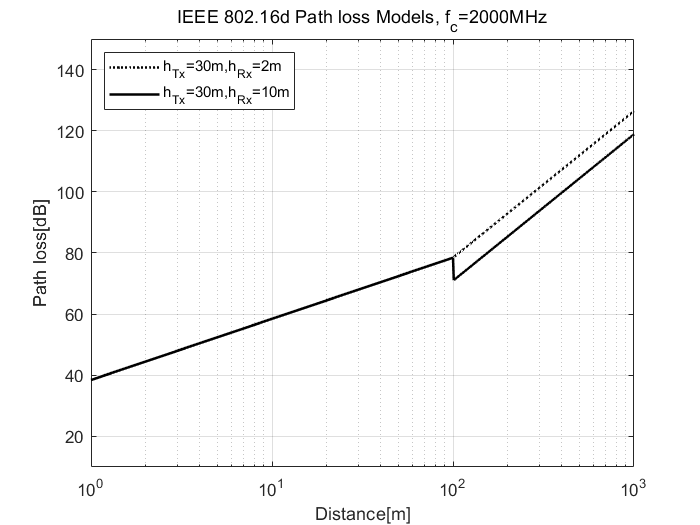

clear,clf,clc
fc = 2e9;
htx = [30 30];
hrx = [2 10];
distance = 1:1000;
y_IEEE16d = zeros(2,length(distance));
y_MIEEE16d = zeros(2,length(distance));
for k = 1:2
    y_IEEE16d(k,:)=PL_IEEE80216d(fc,distance,'A',htx(k),hrx(k),'atnt');
    y_MIEEE16d(k,:)=PL_IEEE80216d(fc,distance,'A',htx(k),hrx(k),'atnt','mod');
end
semilogx(distance,y_IEEE16d(1,:),'k:','LineWidth',1.5),hold on
semilogx(distance,y_IEEE16d(2,:),'k-','LineWidth',1.5)
grid on,axis([1 1000 10 150])
title(['IEEE 802.16d Path loss Models, f_c=',num2str(fc/1e6),'MHz'])
xlabel('Distance[m]'),ylabel('Path loss[dB]')
legend('h_{Tx}=30m,h_{Rx}=2m','h_{Tx}=30m,h_{Rx}=10m','Location','northwest')
hold off

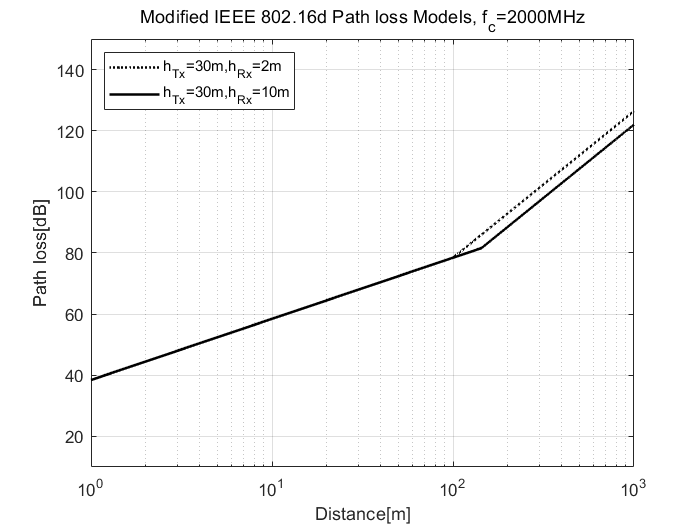

semilogx(distance,y_MIEEE16d(1,:),'k:','LineWidth',1.5),hold on
semilogx(distance,y_MIEEE16d(2,:),'k-','LineWidth',1.5)
grid on,axis([1 1000 10 150])
title(['Modified IEEE 802.16d Path loss Models, f_c=',num2str(fc/1e6),'MHz'])
xlabel('Distance[m]'),ylabel('Path loss[dB]')
legend('h_{Tx}=30m,h_{Rx}=2m','h_{Tx}=30m,h_{Rx}=10m','Location','northwest')